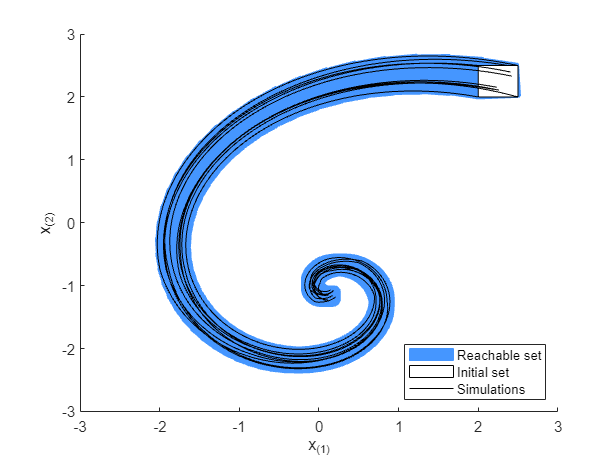

% system dynamics
sys = linearSys([-0.7 -2;2 -0.7],[1;1],[-2;-1]);

% parameter
params.tFinal = 5;
params.R0 = zonotope(interval([2;2],[2.5;2.5]));
params.U = zonotope(interval(-0.1,0.1));

% reachability settings
options.timeStep = 0.05;
options.zonotopeOrder = 10;
options.taylorTerms = 5;

% reachability analysis
R = reach(sys,params,options);

% simulations
simRes = simulateRandom(sys,params);

% plot --------------------------------------------------------------------

figure; hold on;

useCORAcolors("CORA:contDynamics")
plot(R,[1,2],'DisplayName','Reachable set')
plot(R.R0,[1,2],'DisplayName','Initial set')
plot(simRes,[1,2],'DisplayName','Simulations')

legend('Location','southeast')
xlabel('x_{(1)}')
ylabel('x_{(2)}')


exportToHTML(); % for website